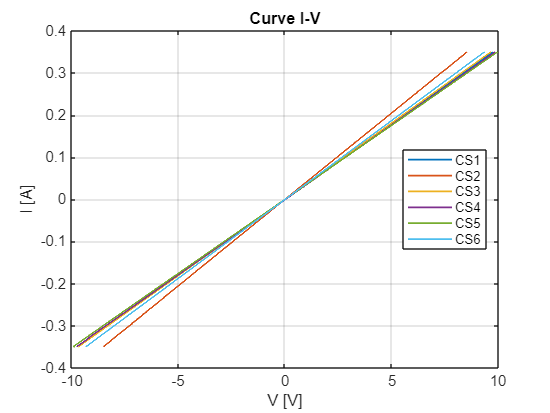

%% Plot I-V da più file .mat (una curva per file)
% Modifica questa riga con la cartella che contiene i file .mat:
cartella = 'Curr';   % '.' = cartella corrente

%% --- Non serve modificare da qui in poi ---

files = dir(fullfile(cartella, '*.mat'));

if isempty(files)
    error('Nessun file .mat trovato in: %s', cartella);
end

figure;
hold on;
grid on;
box on;

legendaLabels = {};

for k = 1:numel(files)
    percorsoFile = fullfile(files(k).folder, files(k).name);
    dati = load(percorsoFile);

    % Controllo che le variabili richieste esistano nel file
    if ~isfield(dati, 'I_meas') || ~isfield(dati, 'V_meas')
        warning('File "%s" saltato: manca I_meas o V_meas.', files(k).name);
        continue;
    end

    I = dati.I_meas(:)*10;
    V = dati.V_meas(:);

    plot(V, I, 'LineWidth', 1.2, 'DisplayName', files(k).name);

    % Nome per la legenda (senza estensione .mat)
    [~, nomeSenzaEst, ~] = fileparts(files(k).name);
    legendaLabels{end+1} = nomeSenzaEst; %#ok<AGROW>
end

xlabel('V [V]');
ylabel('I [A]');
title('Curve I-V');
legend(legendaLabels, 'Interpreter', 'none', 'Location', 'best');

hold off;